# Testing pipeline - PostProcessing Filter in human gait motion 

- read (gait) data 

- gather many data sets and combine

- plot as gait cycle 

- search for error within data

- supposed to work with MP data as well

## create mega struct

-  contains all the data

- unorganized

- analysis -> groups (Settings and stuff tbTested) -> Records

under development, how do we know what signal is the right one, if those names are passed by the user? 

these names could be anything, couldnt they?

## possible signals

'Ninox 120' 

'Ninox 2'

'Ultium Motion'

'Noraxon MyoMotion'

'Video Contacts'

clear;
close;
clc;
%   abc =  load(["C:\Users\Vini\MATLAB Drive\John Studies Drive\analysis\light\Laufband,_Gefälle\2024-04-20-10-18_IMU_Seminar_ebene_gehen.mat"]);
%   initialize struct for saving the datasets
%   each sub-struct contains the same subjects with different Settings:
analysis = struct();
%   sub-structs
%   in future this might be changed by dynamic fields, instead of myomotion
%   we use something like:
%   analysis.("C://PathHere/extractThisFolderName/.matfiles") whereas
%   extractThisFolderName describes a new field.
% under develop
subStruct="";

## Directory access

%   Specify the directory
directoryPath = cd;
filesAndFolders = dir(directoryPath);
%   get rid of ("." , "..")-fields inside filesAndFolders of current directory
%   also while using matlab-Drive the cd contains '.MATLABDriveTag' as field
%   filesAndFolders.name contains the names of folders inside the CD

## filesAndFolders:

blacklist foldernames '.', '..', 'MATLABDriveTag', 'etc.' that cannot be part of the structure

we can pass filesAndFolder.name to 'getPathProperties_2' in order to get rid of hardcoded folder names.

%whitelists for foldernames? blacklist for foldernames that should not be
%included

%blacklisting words that are non-related to data folder
filesAndFolders = filesAndFolders(~ismember({filesAndFolders.name}, {'.', '..','getGroupName.mlx','setSubStructs.mlx','getRecords.mlx','','.MATLABDriveTag','find_riseToFall.mlx','function','normalizeContactsMergePlots.mlx','normalizeAndPlot.mlx','getPathProperties.mlx','getPathProperties_2.mlx','getSignalString.mlx','getSourceSignals.mlx','getSourceContacts.mlx','getNormalizedGait.mlx','setSubChild.mlx','find_intervals.mlx','colorarea.mlx','getContactSwitch.mlx'}));
%   find all .mat  files
fileNames = dir('**/*.mat');

- size( struct2table(fileNames),  1)

## Create subStructs according to folder names

for i = 1:size(struct2table(filesAndFolders),1)
    subStruct(i) = string(filesAndFolders(i).name); %filesAndFolder.name equals the folders name in its order
    %also import here
    %if folder does already exist just paste in the data there
    analysis.(subStruct(i)) = struct();
end
subStruct = subStruct'; 

## combine folder name with folder path

result is a path that is useable for load(), saved in fileNames(i).folder

%   find all .mat files 
for i = 1:size(struct2table(fileNames),1)
    %   brings together path with the filename
    %   filenames(i).folder now contains the explicit path to each individuall .mat file
    %   that is stored inside the current directory
    fileNames(i).folder  = append(fileNames(i).folder,"\",fileNames(i).name);
end

% under develop
% change dir input to dynamic var as well

use a for loop as in example above!!! line 23

offData.paths = dir('off\');
lightData.paths = dir('light\');
moderateData.paths = dir('moderate\');
myoData.paths = dir('Myomotion\');



%checkContain includes the corresponding origin of the File.
% e.g ""C:\Users\Vini\MATLAB Drive\John Studies
% Drive\analysis\light\Laufband,_Gefälle\2024-04-20-10-18_IMU_Seminar_ebene_gehen.mat"
% contains \light\ in its path, therefore the .mat file belongs to the
% struct field "light"

% under develop: we want to have flexible names to look for inside

% getPathProperties, not hardcoded


example for Angle Names

- KneeIndex = checkSignalStrings(record_data01,"Noraxon MyoMotion-Joints-Knee RT-Flexion");

- HipIndex =checkSignalStrings(record_data01,"Noraxon MyoMotion-Joints-Hip RT-Flexion");

- AnkleIndex =checkSignalStrings(record_data01,"Noraxon MyoMotion-Joints-Ankle LT-Dorsiflexion");

pass *input* (fileNames.folder) which contains the exact path to each .mat file

return is a list in order according to the given order from *input*


% cacheFile = getPathProperties_2([fileNames.folder],{"14 14"});
% add a new col(field) called relation to fileNames, which saves the individual
% folder name for each data path
% for i = 1:size(struct2table(fileNames),1)
%     fileNames(i).relation = cacheFile(i);
% end
clear cacheFile; %delete cacheFile from Workspace   

## Seperation into segment angles

get info about the individual origin of the Signal and then pass the wanted angle into the according subStruct.*angle*-Vector

**'Noraxon MyoMotion-Segments-Foot RT-Contact'** 

  " rec.movements.sources.(kameraName).signals."signal_x".data " i.e. 

% runs through each file found earlier...
% saves the .source().signals into      signal
% saves the wanted angle position in    getSignalName

% rather use a dictionary, for mapping movementtypes to joint types
% Knee belongs to Flex 
joint_names = ["Knee", "Hip", "Ankle"];
sides =["RT", "LT"];
movementTypes = ["Flexion","Flexion","Dorsiflexion"];
contact_types = ["RT-Contact", "LT-Contact"];
intervals = [];
% 


for i = 1:size(struct2table(fileNames),1) %struct size
        rec = load(fileNames(i).folder);
        contactSignal = getSourceSignals(rec,"Noraxon MyoMotion");
        %dont look here hehe, need to clean line 88
%       fileName = fileNames(i).name;
        filename = (strrep(append("record_",(strrep(fileNames(i).name,"-","_"))),".mat",""));
    %check if video or myomotion 
    if fileNames(i).relation == "\myomotion\" %hardcoded 
        source_signals = getSourceSignals(rec,"Noraxon MyoMotion"); %This is myoMotion!
    else
        [source_signals, sourceName] = getSourceSignals(rec,"", 1); %exact_id is important here, name does not matter %hardcoded
        time_begin_mp = rec.(filename).movements.time_begin;
        Fs_mp = rec.(filename).movements.sources(1).signals.signal_1.frequency; %sampling frequency
        T_mp = 1/Fs_mp;
        L_mp = rec.(filename).movements.sources(1).signals.signal_1.count;
        t_mp = linspace(0,double(L_mp),double(L_mp)).*T_mp + time_begin_mp; % time vector
    end

    %check all files
    for j = 1:length(joint_names)
                joint = joint_names{j};
                movementType = movementTypes{j}
        %check for each sides
        for ii = 1:length(sides) 
            side = sides{ii};
            contact_type = contact_types{ii};
            if fileNames(i).relation == "\myomotion\" %hardcoded
                signal_label = ['Noraxon MyoMotion-Joints-' joint ' ' side '-' movementType]; %This is myoMotion!
                contactSignal_label = ['Noraxon MyoMotion-Segments-Foot ' contact_type]; 
            else
                signal_label = [ sourceName '-Marks-' joint ' ' movementType ' ' side '-Value Signal' ]; %exact_id is important here, name does not matter %hardcoded
                contactSignal_label = ['Noraxon MyoMotion-Segments-Foot ' contact_type]; 
            end
            

            %fetch signal_label for video 
            %signal_label = [(kameraName) '-Marks-' (joint)' '(movementtype)' '(side)'-Value Signal'];
            % events_side 
            % fetch signal for each side
               
            disp(signal_label);
            signalName = getSignalString(source_signals,signal_label); 
            contactName = getSignalString(contactSignal ,contactSignal_label); %Fetches
            %if signalName was not Found it will be skipped...
            if isempty(signalName)
                if isempty(signalName)
                    continue;
                else
                    disp([signalName(1) " was skipped"]);
                    continue; 
                end                            
            end
            %check the file for each option/group (e.g. "off" "light" "myoMotion"
            %" moderate)
            for k = 1:length(subStruct)
                groupFound = fileNames(i).relation == append("\",subStruct(k),"\");
                %no accordance found
                if ~groupFound
                    fprintf('file %d does not belong to subStruct "%s". \n',i,subStruct(k));
                else                 
                    %fill in first col
                    %save data into the according subStruct but with already
                    %normalized values
                    
                    tempRaw_Signal(:,1) = source_signals.(signalName(1)).data;
                    if fileNames(i).relation == "\myomotion\" %hardcoded
                        
                    else
                        
                    end
                    tempRaw_Signal(:,2) = t_mp;
%                   disp([signalName(1) 'signalname here!']);
                    tempRawContact_Signal = contactSignal.(contactName(1)).data;
                    % indicesContact_Signal = find(tempRawContact_Signal);
                    contact_data = tempRawContact_Signal/1000;
                    footOff_indices = getContactSwitch(contact_data);
                    %check if contactData length is larger in size than
                    %tempRaw_Signal
%                     if length(contact_data) > length(tempRaw_Signal)
%                         %find the indices of the intervall where the
%                         %temp_Raw_Signal is happening
%                         logicvec = ~isnan(tempRaw_Signal);
%                         temp_Signal_intervals = find_riseToFall(logicvec);
%                         tempPro_Signal01 = tempRaw_Signal(temp_Signal_intervals(1,1):temp_Signal_intervals(1,2));
%                         tempPro_Signal02 = tempRaw_Signal(temp_Signal_intervals(2,1):temp_Signal_intervals(2,2));
%                     end
                    
                    jointMovementType = append(joint,movementType);
                    jointMean = append(joint,"Mean"); %convention to always take the joint name with the word Mean appended
                    % AnkleMean / KneeMean / HipMean 
                    analysis = setSubChild(analysis,subStruct(k),side,true);
                    analysis.(subStruct(k)) = setSubChild(analysis.(subStruct(k)),side,jointMovementType,false);
                    intervals = find_intervals(contact_data); %segments intevals for each stride

                    % testVec = getNormalizedGait(tempRaw_Signal,intervals); 
                    % analysis.light.LT.AnkleDorsiflexion
                    %normalized data
                    
                    
                    analysis.(subStruct(k)).(side).(jointMovementType) = getNormalizedGait(tempRaw_Signal,intervals)

                    analysis.(subStruct(k)).(side).(jointMean) = mean(analysis.(subStruct(k)).(side).(jointMovementType),2)
%                   normalizedContactPoints = normalizeContactsMergePlots(analysis.(subStruct(k)).(side).(jointMovementType),intervals,footOff_indices)
                end
                % fprintf(' %d "%s" \n', i, fileNames(i).folder);
            end  %end of options
        end %end of sides
    end %end of joint names
    fprintf('___\n')

end

Unrecognized field name "relation".

## 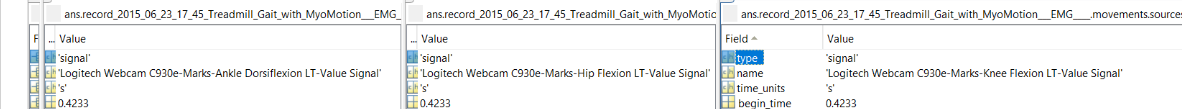

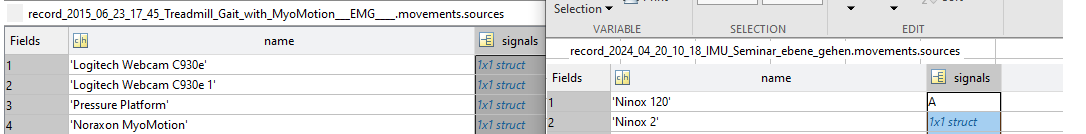

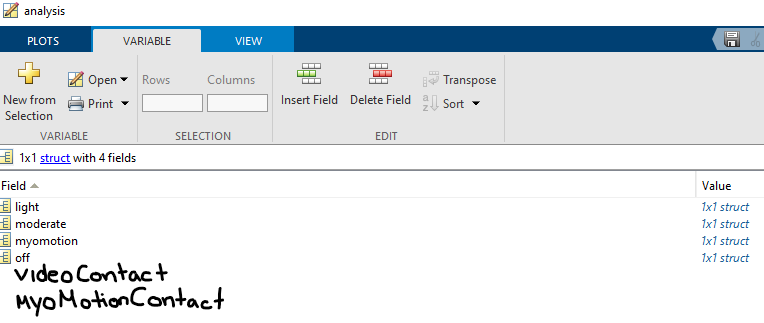 

get video-/FootContact inside that struct. Every Signal should deliver both of these. 

## 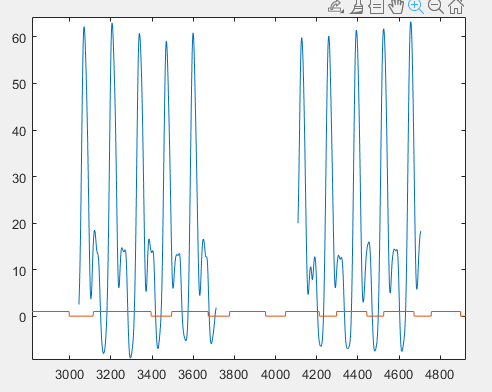

we face a problem when contactData is way larger than ninox data?

we probably need to crop contact data to the size of the ninoxSignal

perhaps these are two different records? 

find where not NaN

## time x-Axis 

## Plot contact_Signal with footOff indices on top of eachother

% figure;
% footOff_indices = footOff_indices';
% plot(contact_data);
% hold on;
% plot(footOff_indices, contact_data(footOff_indices), 'ro');

## plots